## Exemples preprocesament

Revisant el dataset, podem veure que bàsicament els problemes que podem tenir son la lluminositat i el desenfoc

brillant = imread('D:\Documents\VC-MiniProject\Train1\Train1\1\00001_00000_00029.png');
%imshow(brillant);

obscura = imread('D:\Documents\VC-MiniProject\Train1\Train1\1\00001_00012_00025.png');
%imshow(obscura);

desenfocada = imread('D:\Documents\VC-MiniProject\Train1\Train1\1\00001_00013_00022.png');
%aplicar filtre mediana
%montage({brillant, obscura, desenfocada});

Mirant els dos histogrames pels casos de brillantor/obscuritat podem veure:

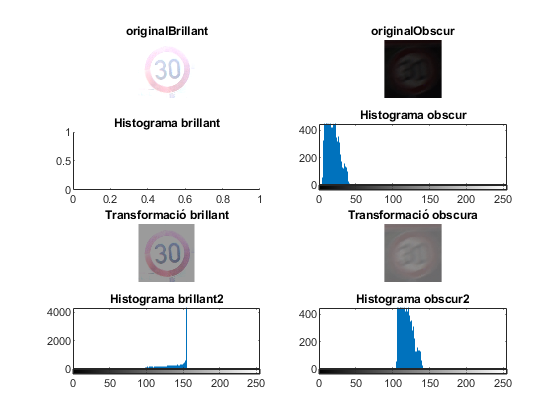

%filas de cuadricula, columnas cuadricula, posición actual:
figure;

subplot(4,2,1)
imshow(brillant); title originalBrillant

subplot(4,2,2)
imshow(obscura); title originalObscur

subplot(4,2,3)
iBri = imhist(brillant);title("Histograma brillant");

subplot(4,2,4)
imhist(obscura);title("Histograma obscur");

subplot(4,2,5)
brillant2 = arrayfun(@(x) x-100,brillant);
imshow(brillant2);title("Transformació brillant");

subplot(4,2,6)
obscura2 = arrayfun(@(x) x+100, obscura);
imshow(obscura2);title("Transformació obscura");

subplot(4,2,7)
imhist(brillant2);title("Histograma brillant2");

subplot(4,2,8)
imhist(obscura2);title("Histograma obscur2");

Hem aplicat uns valors arbitraris, l'objectiu era "centrar" l'histograma. Ara intentem que aquets valors no siguin arbitraris, sino que estiguin relacionats amb l'imatge a tractar:

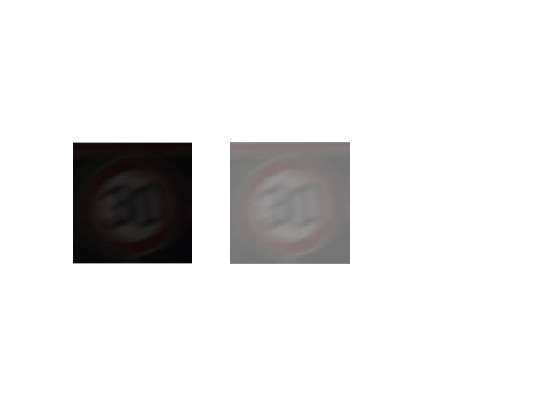

figure
subplot(1,3,1)
imshow(obscura);
x = imhist(obscura);
[M, I] = max(x); % valor del màxim, posició del màxim

dif = 125 - I; %calculem la direncia del maxim amb el centre del histograma:
obscura3 = arrayfun(@(x) x+dif, obscura);
subplot(1,3,2)
imshow(obscura3);